# Tweet Sentiment Database

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Load Data

% Import the data
rawData = parquetread("./datasets/tweet_sentiment_extraction/tweet_sentiment_extraction_bge-large-en-v1.5.parquet", "SelectedVariableNames", ["text", "label_text", "embedding"]);

rawData.label_text = categorical(rawData.label_text);

rawData(1:8, :)

ans = 8×3 table
                                                 text                                                 label_text       embedding   
    ______________________________________________________________________________________________    __________    _______________

    " I`d have responded, if I were going"                                                             neutral      {1024×1 single}
    " Sooo SAD I will miss you here in San Diego!!!"                                                   negative     {1024×1 single}
    "my boss is bullying me..."                                                                        negative     {1024×1 single}
    " what interview! leave me alone"                                                                  negative     {1024×1 single}
    " Sons of ****, why couldn`t they put them on the releases we already bought"        

groupcounts(rawData, "label_text")

ans = 3×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

     negative        7781       28.314 
     neutral        11118       40.457 
     positive        8582       31.229 


## Preperation

sampleSize = 1000;
contamination =0.2;

positiveIndices = find(rawData.label_text == "positive");
negativeIndices = find(rawData.label_text == "negative");

numNegativeSamples = round(contamination * sampleSize);
numPositiveSamples = sampleSize - numNegativeSamples;

negativeSampleIndices = datasample(negativeIndices, numNegativeSamples, "Replace", false);
positiveSampleIndices = datasample(positiveIndices, numPositiveSamples, "Replace", false);
data = rawData(sort(cat(1, positiveSampleIndices, negativeSampleIndices)),:);

clear positiveIndices;
clear negativeIndices;
clear numNegativeSamples;
clear numPositiveSamples;
clear negativeSampleIndices;
clear positiveSampleIndices;
clear rawData;

data.label_text = removecats(data.label_text);
groupcounts(data, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

     negative        200          20   
     positive        800          80   


unlabeledData = cell2mat(cellfun(@transpose,data.embedding,'UniformOutput',false));
centredData = rZscores(unlabeledData);
labels = renamecats(data.label_text, {'positive' 'negative'}, {'inlier' 'outlier'});

## Separability

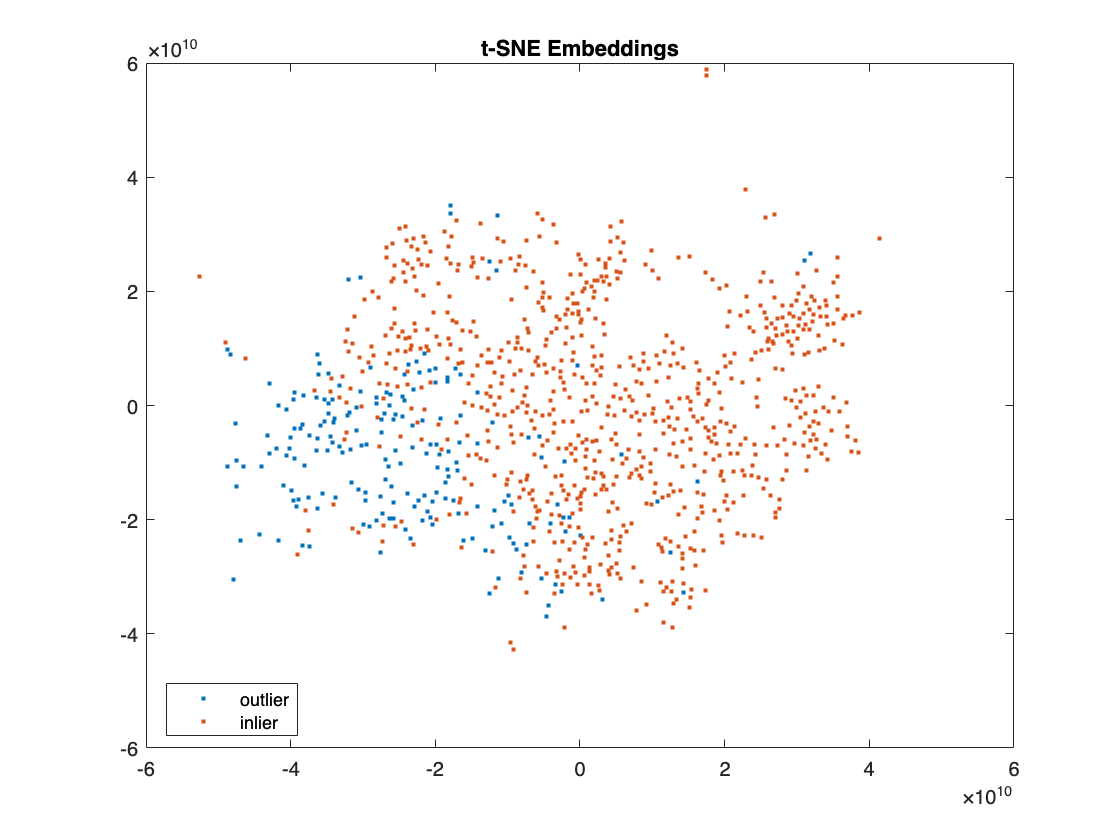

Y = tsne(unlabeledData, Distance="cosine");

figure;
gscatter(Y(:,1),Y(:,2),labels);
title("t-SNE Embeddings");

clear Y;

separabilityindex(unlabeledData, labels, Distance="cosine")

ans = 0.8720

ans = 0.0014

## Computation

alpha = 0.7;
% kModel = AutoRbfKernel(centredData);
kModel = AutoSphereRbfKernel(unlabeledData);

AutoSphereRbfKernel: Sigma = 0.99526290983542


poc = kMRCD(kModel); 
% solution = poc.runAlgorithm(centredData, alpha);
solution = poc.runAlgorithm(unlabeledData, alpha);

Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SpatialRank


## Evaluation

hSubset = data(solution.hsubsetIndices, :);

groupcounts(hSubset, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

     negative        129        18.429 
     positive        571        81.571 


outliers = data(solution.flaggedOutlierIndices, :);

groupcounts(outliers, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

     negative         71        23.355 
     positive        233        76.645 


### Confusion Matrix

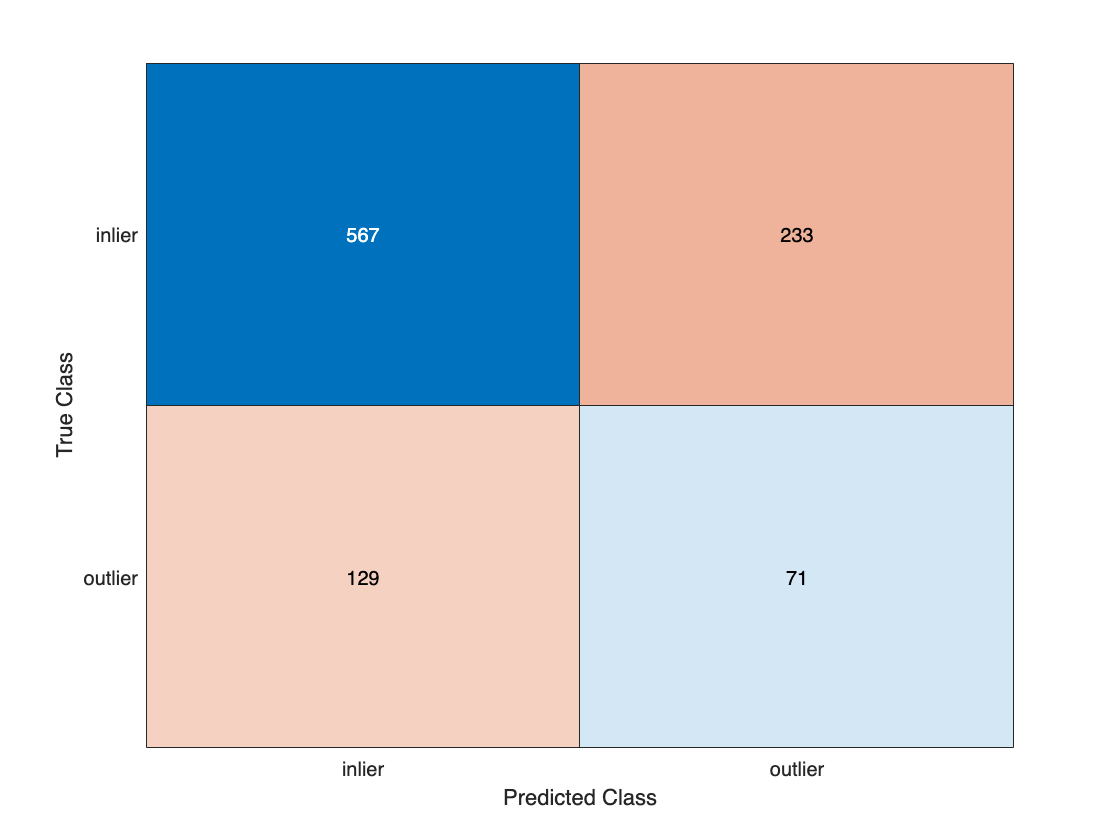

grouphat = categorical(repmat("inlier", size(labels)), categories(labels));
grouphat(solution.flaggedOutlierIndices) = "outlier";

cm = confusionmat(labels,grouphat);
figure;
confusionchart(cm, categories(labels));

struct2table(confusionstats(cm))

ans = 1×5 table
    accuracy    precision    sensitivity    specificity    f1Score
    ________    _________    ___________    ___________    _______

     0.638       0.81466       0.70875         0.355       0.75802


### Mahalanobis Distances

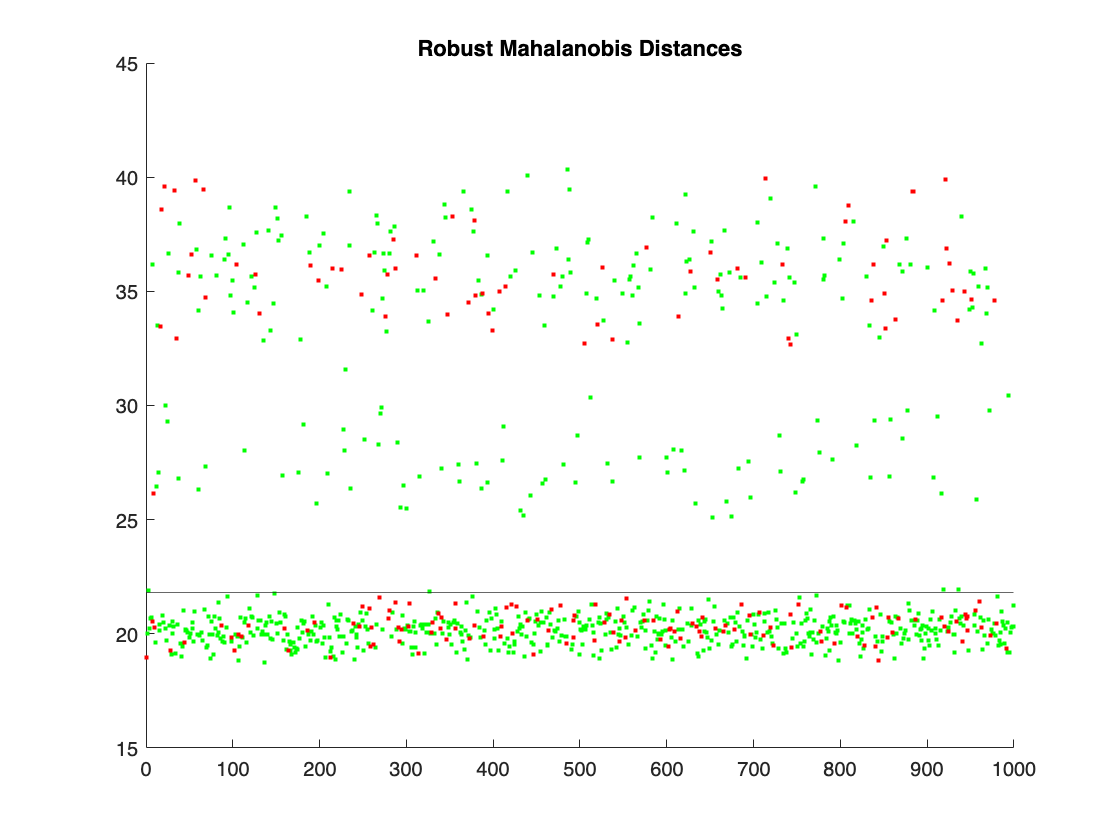

figure;
mahalchart(labels, solution.rd, solution.cutoff);

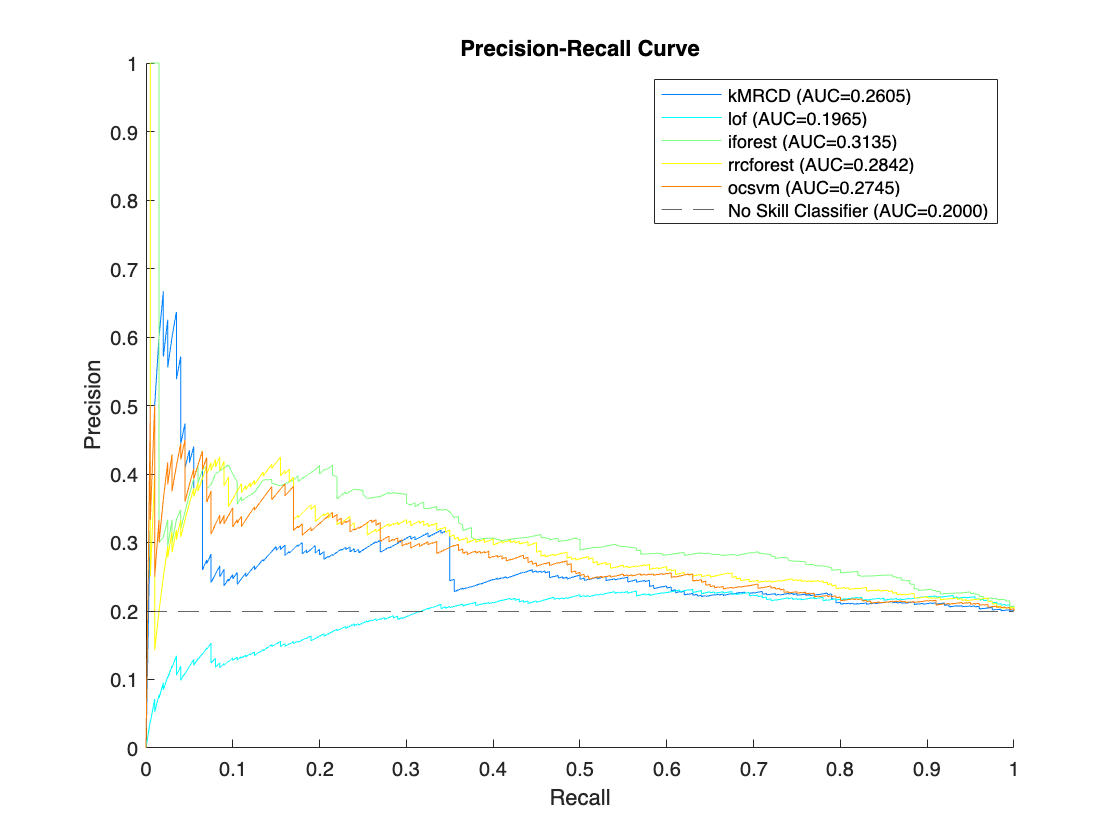

ans = 5×6 table
                 accuracy    precision    sensitivity    specificity    f1Score     aucpr 
                 ________    _________    ___________    ___________    _______    _______

    kMRCD         0.638       0.81466       0.70875         0.355       0.75802    0.26054
    lof           0.614       0.79571       0.69625         0.285       0.74267    0.19649
    iforest       0.686       0.84517       0.74375         0.455       0.79122    0.31348
    rrcforest      0.68       0.84286        0.7375          0.45       0.78667    0.28419
    ocsvm         0.666       0.83286       0.72875         0.415       0.77733    0.27448


evaluation(unlabeledData, labels, alpha, solution)

Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM
Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM
Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM
Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SpatialMedian
Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SpatialRank
Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Conve

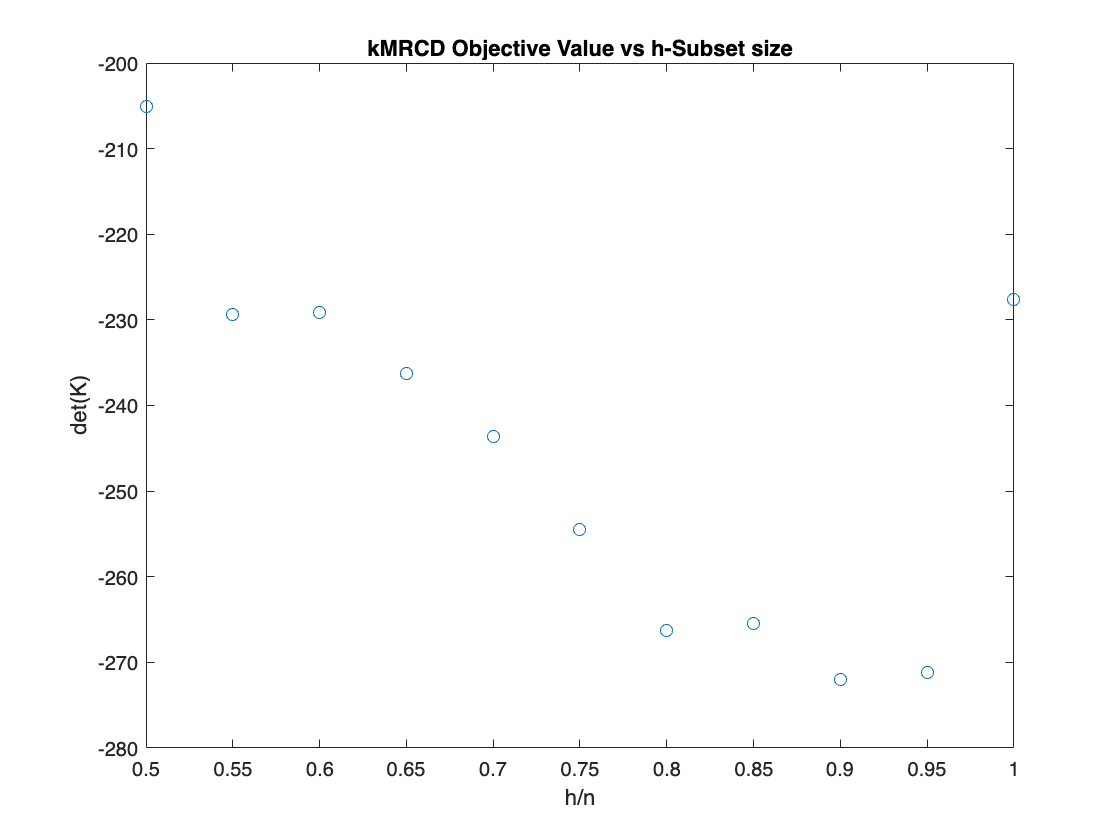

% objectiveplot(poc, centredData);
objectiveplot(poc, unlabeledData);